# ASTE580 HW7

## Problem 1

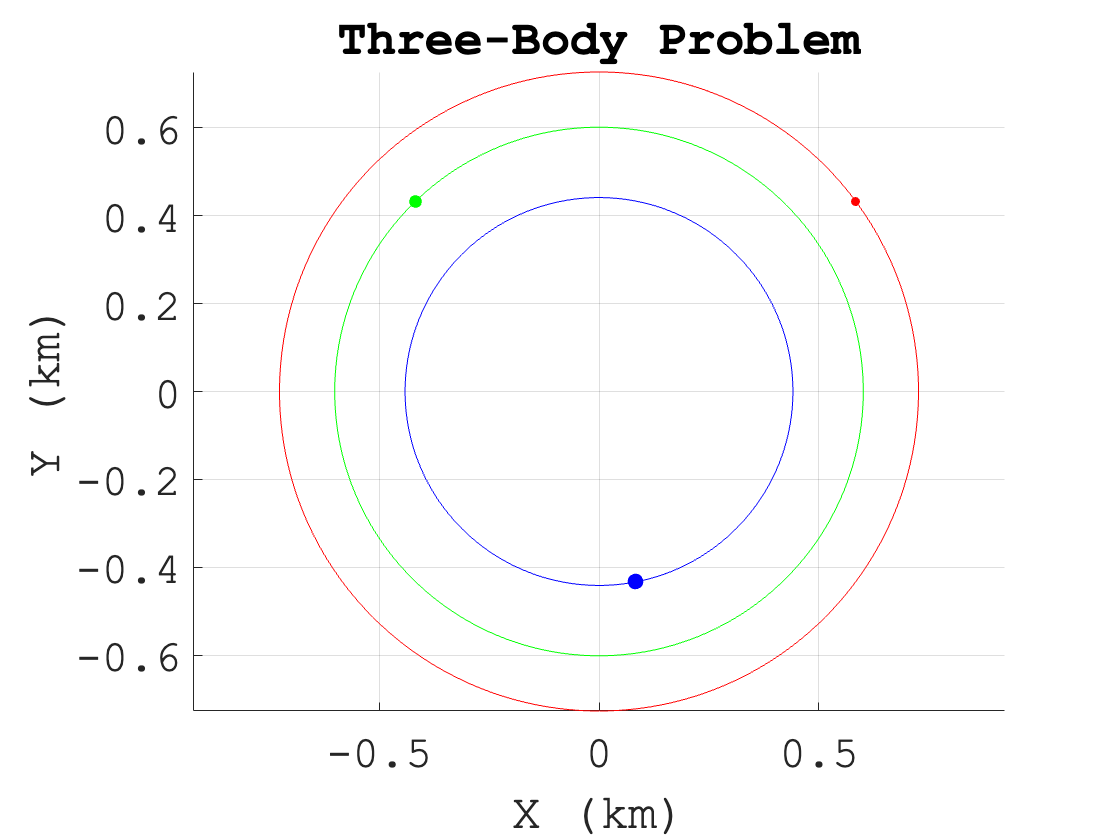

%Constants
m1 = 1;
m2 = 2;
m3 = 3;

%Initial values
r1 = [0; 0];
v1 = [0; 0];

r2 = [1; 0];
v2 = [0; sqrt(6)];

r3 = [1/2; sqrt(3)/2];
v3 = [-3*sqrt(2)/2; sqrt(6)/2];

tspan = linspace(0,pi,1.0e3);
options = odeset('RelTol',1.0e-6,'InitialStep',1.0e-6,'AbsTol',1.0e-6);
[t,X] = ode45(@ode_func,tspan,[r1(1) r1(2) v1(1) v1(2) r2(1) r2(2) v2(1) v2(2) r3(1) r3(2) v3(1) v3(2)],options);

r1 = [X(:,1) X(:,2)];
r2 = [X(:,5) X(:,6)];
r3 = [X(:,9) X(:,10)];
rcm = (m1*r1 + m2*r2 + m3*r3)/(m1 + m2 + m3);

r1 = rcm - r1;
r2 = rcm - r2;
r3 = rcm - r3;

fig = figure(101);
hold on;
p1 = plot(r1(:,1),r1(:,2),'r');
p2 = plot(r2(:,1),r2(:,2),'g');
p3 = plot(r3(:,1),r3(:,2),'b');
s1 = scatter(r1(1,1),r1(1,2),m1*20,'r','filled');
s2 = scatter(r2(1,1),r2(1,2),m2*20,'g','filled');
s3 = scatter(r3(1,1),r3(1,2),m3*20,'b','filled');
axis equal;
grid on;
set(gcf,'Color','w');
set(gca,'Color','w');
set(gca,'FontSize',22,'FontName','Courier New');
title('Three-Body Problem');
xlabel('X (km)');
ylabel('Y (km)');
hold off;

## Problem 2

syms x y mu;

V = 1/2*(x^2 + y^2) + (1 - mu)/sqrt((x + mu)^2 + y^2) + mu/sqrt((x - 1 + mu)^2 + y^2);
dVdx = diff(V,x);
dVdx = simplify(subs(dVdx,y,0))

$$dVdx = x-\frac{\mu \,\left(\mu +x-1\right)}{{\left({\left(\mu +x-1\right)}^{2}\right)}^{3/2}}+\frac{\left(2\,\mu +2\,x\right)\,\left(\mu -1\right)}{2\,{\left({\left(\mu +x\right)}^{2}\right)}^{3/2}}$$

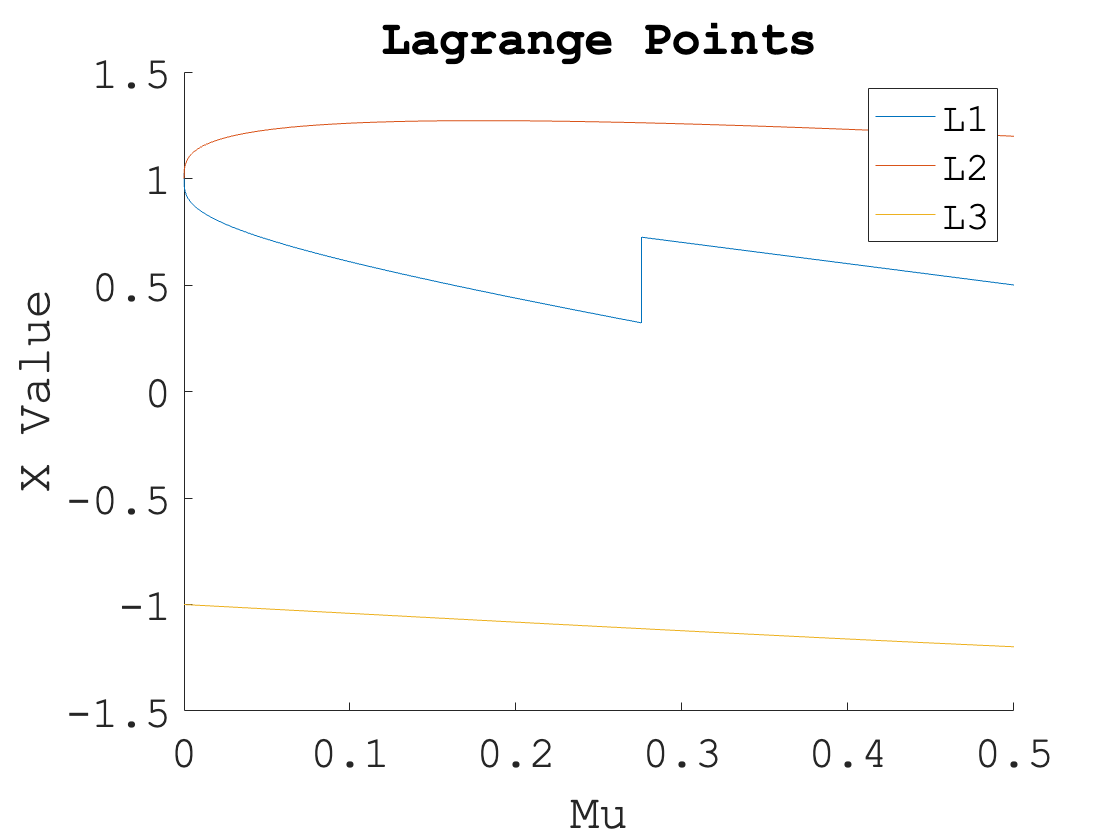

max = 1e4;
L1 = zeros(1,max);
L2 = zeros(1,max);
L3 = zeros(1,max);
mu = linspace(1e-6,0.5,max);
dVdx = @(x,mu) x - (mu*(mu + x - 1))/((mu + x - 1)^2)^(3/2) + ((2*mu + 2*x)*(mu - 1))/(2*((mu + x)^2)^(3/2));
for i = 1:max
    func = @(x) dVdx(x,mu(i));
    L1(i) = fzero(func,1-(mu(i)/3)^(1/3));
    L2(i) = fzero(func,1+(mu(i)/3)^(1/3));
    L3(i) = fzero(func,-1 - (sqrt(2)-1)/3*mu(i));
end

figure();
hold on;
plot(mu,L1);
plot(mu,L2);
plot(mu,L3);
legend('L1','L2','L3');
set(gca,'FontSize',22,'FontName','Courier New');
title('Lagrange Points');
xlabel('Mu');
ylabel('X Value');
hold off;

function dxdt=ode_func(~,x)
%Constants
G = 1;
m1 = 1;
m2 = 2;
m3 = 3;

%Body 1
r1 = [x(1); x(2)];
v1 = [x(3); x(4)];

%Body 2
r2 = [x(5); x(6)];
v2 = [x(7); x(8)];

%Body 3
r3 = [x(9); x(10)];
v3 = [x(11); x(12)];

%Relative vectors
r12 = r2 - r1;
r21 = -r12;
r23 = r3 - r2;
r32 = -r23;
r13 = r3 - r1;
r31 = -r13;

r1 = v1;
v1 = -G*(m2*r21/norm(r21)^3 + m3*r31/norm(r31)^3);
r2 = v2;
v2 = -G*(m1*r12/norm(r12)^3 + m3*r32/norm(r32)^3);
r3 = v3;
v3 = -G*(m1*r13/norm(r13)^3 + m2*r23/norm(r23)^3);

dxdt = [r1(1); r1(2); v1(1); v1(2); r2(1); r2(2); v2(1); v2(2); r3(1); r3(2); v3(1); v3(2)];
end